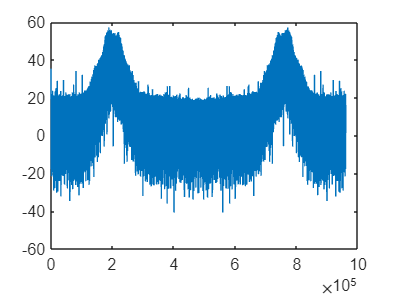

clear;
close all;
syms x t f1 cs csx x1cs s sx x1s x1sj xz;
load('Radio_signal (2).mat')
Fs = 960e3;
Fc = 200e3;
x = raw_radio_94_2MHz;
t = 0:(1/Fs):10;
plot(20*log10(abs(fft(x,Fs))))

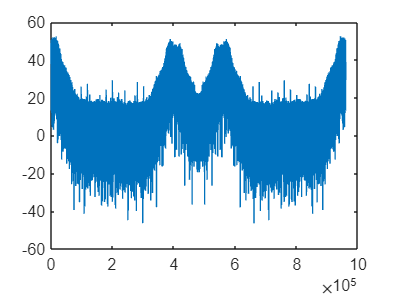

x = x(1:length(t));   %cos
cs = cos(2*pi*Fc*t);
csx = x'.*cs;
plot(20*log10(abs(fft(csx, Fs))))

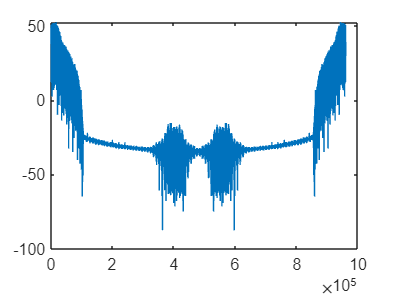

f1 = fir1(101, 0.1875);          %cos lpf
x1cs = filter(f1, 1 , csx);
plot(20*log10(abs(fft(x1cs, Fs))))

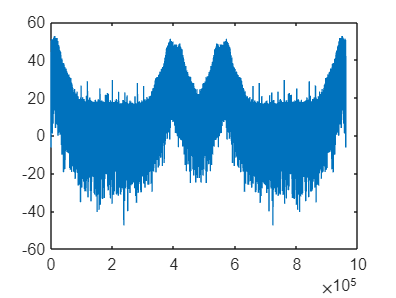

s = -sin(2*pi*Fc*t);          %sin
sx = x'.*s;
plot(20*log10(abs(fft(sx, Fs))))

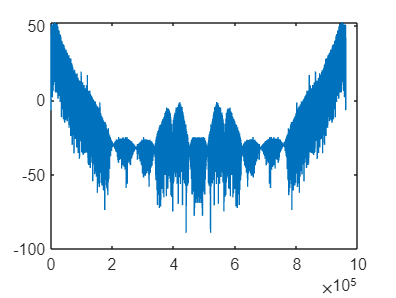

x1s = filter(f1, 1, sx);              %sin lpf
plot(20*log10(abs(fft(x1s, Fs))))

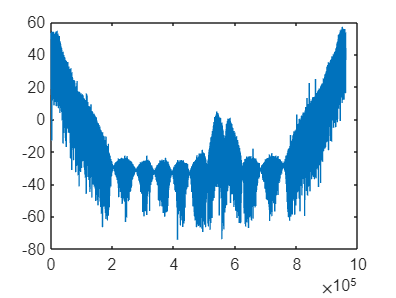

% zespolony
x1sj = x1s * 1j;
xz = x1cs + x1sj;
plot(20*log10(abs(fft(xz, Fs))))

%sprzężenie zwrotne
xz1 = circshift(xz, -1);
xzs = conj(xz1);

y = xz.*xzs;
yn = angle(y);
yds = downsample(yn, 5);
sound(yds, 192000)